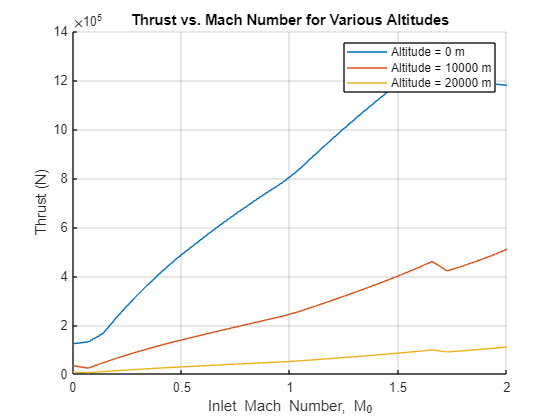

clear; clc; close all;

% Define constants
Gc = 7/5; Gh = 4/3; R = 287; dHB = 4.3e7; % unit: J/kg
To4 = 2000; % Turbine outlet temperatures, unit: K
PR = 25; % Pressure ratios
pi_f = 2; % Fan pressure ratio
To7 = 0;
% Define the constants
Cpc = Gc * R / (Gc - 1); Cph = Gh * R / (Gh - 1);
Ed = 0.97; Ec = 0.85; Eb = 0.99; Et = 0.91; En = 0.97; Eab = 0.98; Ef = 0.87; Efn = 0.97;

% Preallocate the matrices to store results
M0_vector = linspace(0, 2, 30); % Mach number from 0 to 3
altitudes = [0, 10000, 20000]; % Altitudes in meters

% Initialize results
Thrust_results = zeros(length(M0_vector), length(altitudes));

% Loop over altitudes
for a = 1:length(altitudes)
    H = altitudes(a);
    [T0, a0, P0, rho0] = atmosisa(H); % Atmospheric conditions at altitude H
    
    % Loop over Mach numbers
    for m = 1:length(M0_vector)

        M0 = M0_vector(m);
        u0 = M0 * sqrt(Gc * R *T0);
        beta = 8 - 7/2.2*M0; % Dynamic bypass ratio calculation

        % station 2
        [m0, M2, Po2] = inlet_funct_Rev3(M0, P0, T0);
        To2 = T0 * (1 + (Gc-1)/2 * M0^2);

        % station 13
        Po13 = pi_f * Po2;
        To13 = To2 * (1 + (pi_f^((Gc-1)/Gc) - 1) / Ef);

        % station 19
        Po19 = Po13;
        To19 = To13;

        P19 = P0; % Perfectly expanded fan nozzle
        T19 = To13 * (1 - Efn*( 1 - (P19/Po13)^(Gc-1)/Gc ));
        M19 = sqrt( (2/(Gc-1)) * ( (Po19/P19)^((Gc-1)/Gc) - 1 ) );

        u19 = sqrt(Gc*R*T19) * M19;

        % station 3
        Po3 = PR * Po2;
        To3 = To2 * (1 + (PR^((Gc-1)/Gc) - 1) / Ec);

        % station 4
        Tfi = 300; m0_sls = 275; bl = 0.1;
        % [Po4, m4, f] = Rcombustor (To3, Tfi, Po3, To4, Eb, beta, bl, T0, P0, M0, m0_sls);
        % [Po4, m3, m4, f] = Rcombustor (To3, 300, Po3, To4, Eb, beta, 0.1, T0, P0, M0, 275)
        


        Gh = 4/3; Gc = 7/5; R = 287; 
        dHB = 4.3e7; % unit: J/kg
            % beta = 0.25; % beta = m_F / mc
            % bl = 0; % Percentage of the bleed air, m_bl / m_core
            % m0 = 275; % unit: kg/s
        M0_sls = 0; T0_sls = 288.15; P0_sls = 101325;
        To0_sls = T0_sls * (1 + (Gc-1)/2 * M0_sls^2); Po0_sls = P0_sls * (1 + (Gc-1)/2 * M0_sls^2)^(Gc/(Gc-1));
        To0 = T0 * (1 + (Gc-1)/2 * M0^2); Po0 = P0 * (1 + (Gc-1)/2 * M0^2)^(Gc/(Gc-1));
        m0_c = m0_sls * (sqrt(To0_sls/288.15) / (Po0_sls/101325)); % corrected mass flow rate
        m0_fl = m0_c / (sqrt(To0/288.15) / (Po0/101325)); % mass flow rate at the flight condition
    
        M3 = 0.3; % Assume the inlet Mach number
        m3 = m0_fl * (1/ (1+beta)); % Core flow at station 3
        m31 = m3 * (1-bl); % Core flow at station 31
    
        D3 = M3/ ( 1 + (Gc-1)/2 * M3^2 )^ ( (Gc+1)/2/(Gc-1) );
        A3 = m31 *sqrt(To3*R/Gc) / Po3 / D3; % unit: m^2
    
        N = 10; % Number of control volumes dividing the combustor
    
        % Preallocate arrays
        To = zeros(N+1, 1); M = zeros(N+1, 1); A = zeros(N+1, 1); Po = zeros(N+1, 1);
        To(1) = To3; M(1) = M3; Po(1) = Po3; A(1) = 1; %A3; % Set inlet conditions
    
        TD = (To4 - To3) / (N-1);
        for n = 2:N+1
            To(n) = TD + To(n-1);
            TR = To(n) / To(n-1);        
            M(n) = sqrt(M(n-1)^2 / (TR + (Gh-1)/2 * M(n-1)^2 * (TR-1))); % M at the outlet of cell n
            
            PoR(n-1) = ( (1 + (Gh-1)/2 * M(n)^2)/(1 + (Gh-1)/2 * M(n-1)^2) )^ (Gh / (Gh-1));
            Po(n) = PoR(n-1) * Po(n-1);
            A(n) = A(n-1) * (M(n-1) / M(n))^2;  % Example calculation for area ratio
            AR(n-1) = A(n) / A(n-1);
        end

    % Calculate the Total Pressure Loss
    PL = max(Po) - min (Po);
    Po4 = max(Po);

    % Calculate the fuel-air ratio and fuel mass flow rate
    Hv = 3.6e5; % the latent heat of evaporation
    [Cpfi, ~] = CP_f(Tfi, false); [Cpf4, ~] = CP_f(To4, false); % Cp for the fuel
    [~, Cpa3] = CP_f(To3, false); [~, Cpa4] = CP_f(To4, false); % Cp for the air
    
    CA = Cpfi*Tfi + Cpf4*To4 - Eb*dHB;
    CB = -Cpfi*Tfi + Cpa4*To4 + Hv - Cpa3*To3 -Cpf4*To4 - Eb*dHB;
    CC = -Cpa3*To3 + Cpa4*To4; 
    f_roots = roots([CA, CB, CC]);        
    positive_f = f_roots(f_roots > 0); % Select positive root
    f = positive_f;
    mf = m31 * positive_f;
    m4 = mf + m31;



        % station 5
        To5 = To4 - (m3*Cpc)/(m4*Cph) * ((To3 - To2) - beta*(To13-To2));
                
        Po5 = Po4 * (1 - ((1 - To5/To4) / Et))^(Gh/(Gh-1));
            
        if f < 0 || To5 < 0
            continue % The engine can't operate at this flight condition; skip the current iteration
        end

        % station 7
        Po7 = Po5;
        To5 = To5;
        
        fab = (1+f) * (Cph*To7 - Cpc*To5) / (Eab*dHB - Cph*To7);
        
        % station 9
        u9_f = sqrt(2*Cph*To5*En * ( 1-(P0/Po5)^((Gh-1)/Gh) ));
        u9_ab = sqrt(2*Cph*To7*En * ( 1-(P0/Po7)^((Gh-1)/Gh) ));
        
        % Calculate Specific Thrust and SFC
        if beta ==0
            u9 = u9_ab;
        else
            u9 = u9_f;
            fab = 0;
        end

        % Exit conditions and thrust calculation
        u9 = sqrt(2*Cph*To5*En * (1 - (P0/Po5)^((Gh-1)/Gh)));
        ST = (1+f)/(1+beta)*u9 - 1/(1+beta)*u0 + beta/(1+beta) * (u19 - M0*sqrt(Gc*R*T0));

        % Store Specific Thrust for plotting
        Thrust_results(m, a) = ST * m0;

    end
end

% Plotting
figure;
hold on;
colors = lines(length(altitudes));
for a = 1:length(altitudes)
    plot(M0_vector, Thrust_results(:, a), 'Color', colors(a, :), 'DisplayName', sprintf('Altitude = %d m', altitudes(a)));
end
xlabel('Inlet Mach Number, M_0');
ylabel('Thrust (N)');
title('Thrust vs. Mach Number for Various Altitudes');
legend('show');
grid on;
hold off;

**Real Combustor Analysis**

function [Po4, m3, m4, f] = Rcombustor (To3, Tfi, Po3, To4, Eb, beta, bl, T0, P0, M0, m0_sls)
    Gh = 4/3; Gc = 7/5; R = 287; 
    dHB = 4.3e7; % unit: J/kg
        % beta = 0.25; % beta = m_F / mc
        % bl = 0; % Percentage of the bleed air, m_bl / m_core
        % m0 = 275; % unit: kg/s
    M0_sls = 0; T0_sls = 288.15; P0_sls = 101325;
    To0_sls = T0_sls * (1 + (Gc-1)/2 * M0_sls^2); Po0_sls = P0_sls * (1 + (Gc-1)/2 * M0_sls^2)^(Gc/(Gc-1));
    To0 = T0 * (1 + (Gc-1)/2 * M0^2); Po0 = P0 * (1 + (Gc-1)/2 * M0^2)^(Gc/(Gc-1));
    m0_c = m0_sls * (sqrt(To0_sls/288.15) / (Po0_sls/101325)); % corrected mass flow rate
    m0_fl = m0_c / (sqrt(To0/288.15) / (Po0/101325)); % mass flow rate at the flight condition

    M3 = 0.3; % Assume the inlet Mach number
    m3 = m0_fl * (1/ (1+beta)); % Core flow at station 3
    m31 = m3 * (1-bl); % Core flow at station 31

    D3 = M3/ ( 1 + (Gc-1)/2 * M3^2 )^ ( (Gc+1)/2/(Gc-1) );
    A3 = m31 *sqrt(To3*R/Gc) / Po3 / D3; % unit: m^2

    N = 10; % Number of control volumes dividing the combustor

    % Preallocate arrays
    To = zeros(N+1, 1); M = zeros(N+1, 1); A = zeros(N+1, 1); Po = zeros(N+1, 1);
    To(1) = To3; M(1) = M3; Po(1) = Po3; A(1) = 1; %A3; % Set inlet conditions

    TD = (To4 - To3) / (N-1);
    for n = 2:N+1
        To(n) = TD + To(n-1);
        TR = To(n) / To(n-1);        
        M(n) = sqrt(M(n-1)^2 / (TR + (Gh-1)/2 * M(n-1)^2 * (TR-1))); % M at the outlet of cell n
        
        PoR(n-1) = ( (1 + (Gh-1)/2 * M(n)^2)/(1 + (Gh-1)/2 * M(n-1)^2) )^ (Gh / (Gh-1));
        Po(n) = PoR(n-1) * Po(n-1);
        A(n) = A(n-1) * (M(n-1) / M(n))^2;  % Example calculation for area ratio
        AR(n-1) = A(n) / A(n-1);
    end

    % Calculate the Total Pressure Loss
    PL = max(Po) - min (Po);
    Po4 = max(Po);

    % Calculate the fuel-air ratio and fuel mass flow rate
    Hv = 3.6e5; % the latent heat of evaporation
    [Cpfi, ~] = CP_f(Tfi, false); [Cpf4, ~] = CP_f(To4, false); % Cp for the fuel
    [~, Cpa3] = CP_f(To3, false); [~, Cpa4] = CP_f(To4, false); % Cp for the air
    
    CA = Cpfi*Tfi + Cpf4*To4 - Eb*dHB;
    CB = -Cpfi*Tfi + Cpa4*To4 + Hv - Cpa3*To3 -Cpf4*To4 - Eb*dHB;
    CC = -Cpa3*To3 + Cpa4*To4; 
    f_roots = roots([CA, CB, CC]);        
    positive_f = f_roots(f_roots > 0); % Select positive root
    f = positive_f;
    mf = m31 * positive_f;
    m4 = mf + m31;
end

**Cp curve fitting**

function [CPJA_v, CPa_v] = CP_f(Tin, showPlot)
    % returns specific heat values for Jet-A vapor, Jet-A liquid, and air
    % INPUTS-showPlot: Boolean flag to indicate whether to show plots (true/false)
   
    % Load data
    data = readtable('C:\Users\SJ Chen\OneDrive - purdue.edu\Purdue\2024Fall\AAE538 Air-Breathing Propulsion\Project\Specificheat.csv'); 

     T = data.T;          % Temperature in K
    CPJAg = data.CPJAg;  % Specific heat of Jet-A vapor in J/kg/K
    CPJAL = data.CPJAL;  % Specific heat of Jet-A liquid in J/kg/K
    CPa = data.CPa;      % Specific heat of air in J/kg/K

    % Create spline representations of the variables
    CPJAg_spline = spline(T, CPJAg);
    CPJAL_spline = spline(T(~isnan(CPJAL)), CPJAL(~isnan(CPJAL)));  % Use only non-NaN entries
    CPa_spline = spline(T, CPa);

    % Check if input temperature is within the range of the data
    if Tin < min(T) || Tin > max(T)
        error('Input temperature is out of range of the available data.');
    end

    % Evaluate specific heat for air at the input temperature
    CPa_v = ppval(CPa_spline, Tin);

    % Determine specific heat for Jet-A (liquid or vapor depending on temperature)
    if Tin <= max(T(~isnan(CPJAL)))
        % If the temperature is within the range of Jet-A liquid, use CPJAL
        CPJA_v = ppval(CPJAL_spline, Tin);
    else
        % Otherwise, use Jet-A vapor specific heat
        CPJA_v = ppval(CPJAg_spline, Tin);
    end

    % Plotting if showPlot is true
    if showPlot
        % Define a finer temperature range for plotting the splines
        T_fine = linspace(min(T), max(T), 300);
        T_fine_JL = linspace(min(T(~isnan(CPJAL))), max(T(~isnan(CPJAL))), 300);  % Only within the valid range of CPJAL

        % Evaluate splines on the finer temperature grid
        CPJAg_fine = ppval(CPJAg_spline, T_fine);
        CPJAL_fine = ppval(CPJAL_spline, T_fine_JL);
        CPa_fine = ppval(CPa_spline, T_fine);

        % Plotting
        figure;

        % Specific heat of Jet-A vapor
        subplot(3,1,1); 
        plot(T, CPJAg, 'o', T_fine, CPJAg_fine, '-'); 
        title('Specific Heat Capacity of Jet-A Vapor'); 
        xlabel('Temperature (K)'); ylabel('CP (J/kg/K)');

        % Specific heat of Jet-A liquid
        subplot(3,1,2); 
        plot(T(~isnan(CPJAL)), CPJAL(~isnan(CPJAL)), 'o', T_fine_JL, CPJAL_fine, '-'); 
        title('Specific Heat Capacity of Jet-A Liquid'); 
        xlabel('Temperature (K)'); ylabel('CP (J/kg/K)');

        % Specific heat of air
        subplot(3,1,3); 
        plot(T, CPa, 'o', T_fine, CPa_fine, '-'); 
        title('Specific Heat Capacity of Air'); 
        xlabel('Temperature (K)'); ylabel('CP (J/kg/K)');
    end
end